# Resize Figure Snapshot Image

This example generates a PDF report that illustrates the difference between resizing a figure snapshot image using the `print` command and resizing using the reporter specified by the `Snapshot` property of the `Figure` reporter.

Create a wide MATLAB® figure. Create three `mlreportgen.report.Figure` reporters from the figure and add them to a report.

- The first `Figure` reporter does not resize the figure.

- The second `Figure` reporter uses the `print` command to resize the figure.

- `The` third `Figure` reporter uses the `Snapshot` reporter to resize the figure.

import mlreportgen.report.*

fig = figure();
ax = axes(fig);
plot(ax, rand(1,100));

pos = fig.Position;
fig.Position = [pos(1) pos(2) 2*pos(3) pos(4)];

rpt = Report('example','pdf');

add(rpt, "Intrinsic figure size");
figReporter0 = Figure(fig);
figReporter0.Scaling = 'none';
add(rpt,figReporter0);

add(rpt, "Resized by print command");
figReporter1 = Figure(fig);
add(rpt,figReporter1);

add(rpt, "Resized by snapshot reporter");
figReporter2 = Figure(fig);
figReporter2.Scaling = 'none';
figReporter2.Snapshot.ScaleToFit = true;
add(rpt,figReporter2);

close(rpt);
delete(fig)
rptview(rpt);

Here are the figures in the generated report:

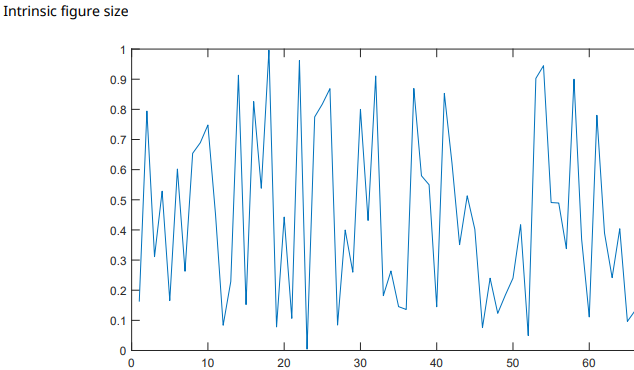

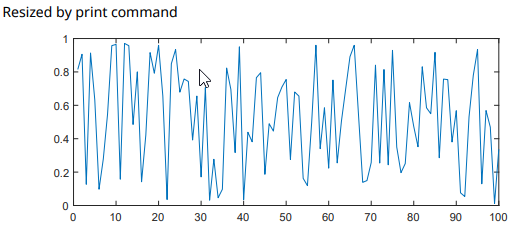

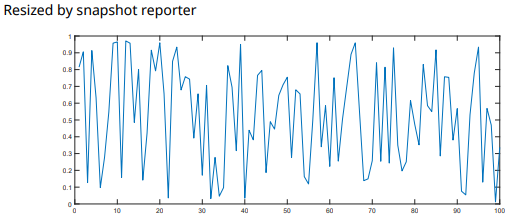

*Copyright 2019 The MathWorks, Inc.*